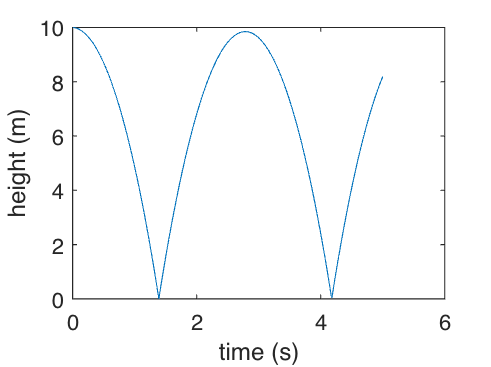

% Problem 1
dt = 0.01;
t = 0:dt:5;
yi = 10;
ydot=0;
g = 9.81;
c_d = 0.01;
x = 1:length(t);
y = 1:length(t);
y(1) = 10;
for i = x
    tn = t(i);
    if tn == 0
        yddot = -g;
        ydot = ydot+yddot*dt;
        %no setting y since y(1) = 10 already set
    else
        yddot = -g-c_d*ydot^2;
        ydot = ydot+yddot*dt;
        y(i) = y(i-1)+ydot*dt;
        if y(i)<=0
            ydot = abs(ydot);
            y(i) = abs(y(i));
        end
    end
end
plot(t,y)
xlabel("time (s)")
ylabel("height (m)")


% Problem 2
s = tf('s');
t = 0:0.01:5;
cur = (12/4.7)*(1-(exp(1)).^(-47*t))

cur =          0    0.9574    1.5558    1.9298    2.1636    2.3097    2.4010    2.4581    2.4937    2.5160    2.5300    2.5387    2.5441    2.5475    2.5496    2.5510    2.5518    2.5523    2.5527    2.5529    2.5530    2.5531    2.5531    2.5531    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532    2.5532


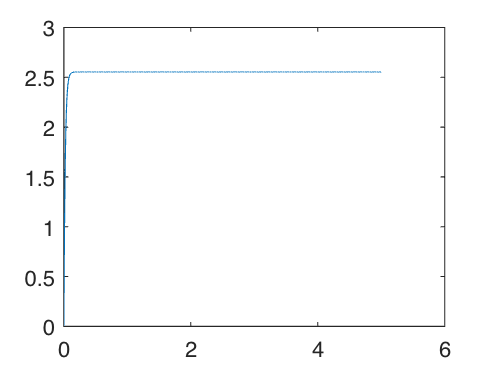

plot(t,cur)

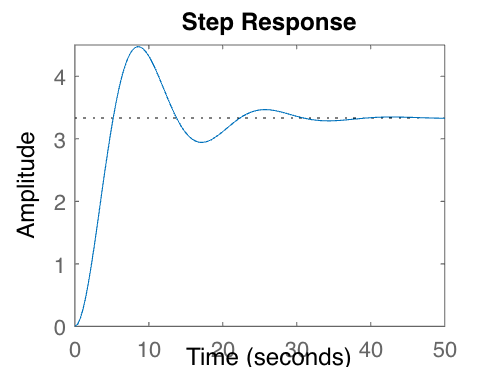


m=2;
b=0.5;
k=0.3;
step(1/(m*s^2+b*s+k))

w_n = sqrt(k/m)

w_n = 0.3873

zeta = (b/2)*sqrt(m/k)

zeta = 0.6455

K = 1/k

K = 3.3333

os = (exp(1))^(-zeta*pi/sqrt(1-zeta^2))*100

os = 7.0290

ts = 4/(zeta*w_n)

ts = 16

tr = 1.8/w_n

tr = 4.6476